# Laboratorio 2

**Diego Carvajal - Duvan Lizarazo**

clc
clear

## **Importar base de datos de Hepatitis**

datafile = pwd + "\hepatiti.pat";
hepatiti = importHepatitis(datafile);
hepatiti = table2array(hepatiti);

val_accu_mat = zeros(150,10);
test_accu_mat = zeros(150,10);

for j=1:150

## Separar datos de entrenamiento y test

Dividir el 60% de los datos de forma aleatoria para entrenamiento y el 30% restante para pruebas

    [m,~] = size(hepatiti);
    [train_index,val_index,test_index] = dividerand(m,0.69,0.2,0.2);
    train_data = hepatiti(train_index,:);
    val_data = hepatiti(val_index,:);
    test_data = hepatiti(test_index,:);

Separar las columnas de variables de las de clases

    train_var = train_data(:,1:end-2);
    train_class = train_data(:,end-1:end);
    
    val_var = val_data(:,1:end-2);
    val_class = val_data(:,end-1:end);
    
    test_var = test_data(:,1:end-2);
    test_class = test_data(:,end-1:end);

## Calcular los centroides de cada clase

    train_c1 = train_var(train_class(:,1) == 0 & train_class(:,2) == 1,:);
    cent_train_c1 = mean(train_c1);
    train_c2 = train_var(train_class(:,1) == 1 & train_class(:,2) == 0,:);
    cent_train_c2 = mean(train_c2);

## Distancia Euclídea

### Predicción

#### Prediccion de datos de validación

    [valm,~] = size(val_class);
    val_vclass = zeros(valm,1);
    for i=1:valm
        if val_class(i,1)==0 && val_class(i,2)==1
            val_vclass(i,1) = 1;
        else
            val_vclass(i,1) = 2;
        end
    end
    val_pclass = zeros(valm,1);
    for i=1:valm
        if pdist2(cent_train_c1,test_var(i,:)) < pdist2(cent_train_c2,...
                test_var(i,:))
        val_pclass(i,1) = 1;
        else
            val_pclass(i,1) = 2;
        end
    end
    
    val_conf = confusionmat(val_vclass,val_pclass);
    %confusionchart(test_conf);

#### Prediccion de datos de prueba

    [tsm,~] = size(test_class);
    test_vclass = zeros(tsm,1);
    for i=1:tsm
        if test_class(i,1)==0 && test_class(i,2)==1
            test_vclass(i,1) = 1;
        else
            test_vclass(i,1) = 2;
        end
    end
    test_pclass = zeros(tsm,1);
    for i=1:tsm
        if pdist2(cent_train_c1,test_var(i,:)) < pdist2(cent_train_c2,...
                test_var(i,:))
        test_pclass(i,1) = 1;
        else
            test_pclass(i,1) = 2;
        end
    end
    
    test_conf = confusionmat(test_vclass,test_pclass);
    %confusionchart(test_conf)

### Accuracy

    val_accu = (val_conf(2,2)+val_conf(1,1))/(sum(val_conf,'all'))*100;
    test_accu = (test_conf(2,2)+test_conf(1,1))/(sum(test_conf,'all'))*100;
    
    val_accu_mat(j,1) = val_accu;
    test_accu_mat(j,1) = test_accu;

### Sensitivity

    euc_val_sens = val_conf(2,2)/(val_conf(2,2)+val_conf(2,1))*100;
    euc_test_sens = test_conf(2,2)/(test_conf(2,2)+test_conf(2,1))*100;

### Precision

    ecu_val_prec = val_conf(2,2)/(val_conf(2,2)+val_conf(1,2))*100;
    ecu_test_prec = test_conf(2,2)/(test_conf(2,2)+test_conf(1,2))*100;
    

## Distancia Euclídea Cuadrada

### Predicción

#### Prediccion de datos de validación

    [valm,~] = size(val_class);
    val_vclass = zeros(valm,1);
    for i=1:valm
        if val_class(i,1)==0 && val_class(i,2)==1
            val_vclass(i,1) = 1;
        else
            val_vclass(i,1) = 2;
        end
    end
    val_pclass = zeros(valm,1);
    for i=1:valm
        if pdist2(cent_train_c1,test_var(i,:)) < pdist2(cent_train_c2,...
                test_var(i,:),"squaredeuclidean")
        val_pclass(i,1) = 1;
        else
            val_pclass(i,1) = 2;
        end
    end
    
    val_conf = confusionmat(val_vclass,val_pclass);
    %confusionchart(test_conf);

#### Prediccion de datos de prueba

    [tsm,~] = size(test_class);
    test_vclass = zeros(tsm,1);
    for i=1:tsm
        if test_class(i,1)==0 && test_class(i,2)==1
            test_vclass(i,1) = 1;
        else
            test_vclass(i,1) = 2;
        end
    end
    test_pclass = zeros(tsm,1);
    for i=1:tsm
        if pdist2(cent_train_c1,test_var(i,:)) < pdist2(cent_train_c2,...
                test_var(i,:),"squaredeuclidean")
        test_pclass(i,1) = 1;
        else
            test_pclass(i,1) = 2;
        end
    end
    
    test_conf = confusionmat(test_vclass,test_pclass);
    %confusionchart(test_conf)

### Accuracy

    val_accu = (val_conf(2,2)+val_conf(1,1))/(sum(val_conf,'all'))*100;
    test_accu = (test_conf(2,2)+test_conf(1,1))/(sum(test_conf,'all'))*100;
    
    val_accu_mat(j,2) = val_accu;
    test_accu_mat(j,2) = test_accu;

## Distancia Euclídea Estandar

### Predicción

#### Prediccion de datos de validación

    %     [valm,~] = size(val_class);
    %     val_vclass = zeros(valm,1);
    %     for i=1:valm
    %         if val_class(i,1)==0 && val_class(i,2)==1
    %             val_vclass(i,1) = 1;
    %         else
    %             val_vclass(i,1) = 2;
    %         end
    %     end
    %     val_pclass = zeros(valm,1);
    %     for i=1:valm
    %         if pdist2(cent_train_c1,test_var(i,:)) < ...
    %  pdist2(cent_train_c2,test_var(i,:),"seuclidean")
    %             val_pclass(i,1) = 1;
    %         else
    %             val_pclass(i,1) = 2;
    %         end
    %     end
    %
    %     val_conf = confusionmat(val_vclass,val_pclass);
    %     %confusionchart(test_conf);

#### Prediccion de datos de prueba

    %     [tsm,~] = size(test_class);
    %     test_vclass = zeros(tsm,1);
    %     for i=1:tsm
    %         if test_class(i,1)==0 && test_class(i,2)==1
    %             test_vclass(i,1) = 1;
    %         else
    %             test_vclass(i,1) = 2;
    %         end
    %     end
    %     test_pclass = zeros(tsm,1);
    %     for i=1:tsm
    %         if pdist2(cent_train_c1,test_var(i,:)) < ...
    % pdist2(cent_train_c2,test_var(i,:),"seuclidean")
    %             test_pclass(i,1) = 1;
    %         else
    %             test_pclass(i,1) = 2;
    %         end
    %     end
    %
    %     test_conf = confusionmat(test_vclass,test_pclass);
    %     %confusionchart(test_conf)

### Accuracy

    %     euc_std_val_accu = (val_conf(2,2)+val_conf(1,1))/(sum(val_conf,'all'))*100;
    %     euc_std_test_accu = (test_conf(2,2)+test_conf(1,1))/(sum(test_conf,'all'))*100;
    %
    %     val_accu_mat(j,3) = euc_std_val_accu;
    %     test_accu_mat(j,3) = euc_std_test_accu;

## Distancia Cityblock

### Predicción

#### Prediccion de datos de validación

    [valm,~] = size(val_class);
    val_vclass = zeros(valm,1);
    for i=1:valm
        if val_class(i,1)==0 && val_class(i,2)==1
            val_vclass(i,1) = 1;
        else
            val_vclass(i,1) = 2;
        end
    end
    val_pclass = zeros(valm,1);
    for i=1:valm
        if pdist2(cent_train_c1,test_var(i,:)) < pdist2(cent_train_c2,...
                test_var(i,:),"cityblock")
        val_pclass(i,1) = 1;
        else
            val_pclass(i,1) = 2;
        end
    end
    
    val_conf = confusionmat(val_vclass,val_pclass);
    %confusionchart(test_conf);

#### Prediccion de datos de prueba

    [tsm,~] = size(test_class);
    test_vclass = zeros(tsm,1);
    for i=1:tsm
        if test_class(i,1)==0 && test_class(i,2)==1
            test_vclass(i,1) = 1;
        else
            test_vclass(i,1) = 2;
        end
    end
    test_pclass = zeros(tsm,1);
    for i=1:tsm
        if pdist2(cent_train_c1,test_var(i,:)) < pdist2(cent_train_c2,...
                test_var(i,:),"cityblock")
        test_pclass(i,1) = 1;
        else
            test_pclass(i,1) = 2;
        end
    end
    
    test_conf = confusionmat(test_vclass,test_pclass);
    %confusionchart(test_conf)

### Accuracy

    val_accu = (val_conf(2,2)+val_conf(1,1))/(sum(val_conf,'all'))*100;
    test_accu = (test_conf(2,2)+test_conf(1,1))/(sum(test_conf,'all'))*100;
    
    val_accu_mat(j,4) = val_accu;
    test_accu_mat(j,4) = test_accu;

## Distancia Chebychev

### Predicción

#### Prediccion de datos de validación

    [valm,~] = size(val_class);
    val_vclass = zeros(valm,1);
    for i=1:valm
        if val_class(i,1)==0 && val_class(i,2)==1
            val_vclass(i,1) = 1;
        else
            val_vclass(i,1) = 2;
        end
    end
    val_pclass = zeros(valm,1);
    for i=1:valm
        if pdist2(cent_train_c1,test_var(i,:)) < pdist2(cent_train_c2,...
                test_var(i,:),"chebychev")
        val_pclass(i,1) = 1;
        else
            val_pclass(i,1) = 2;
        end
    end
    
    val_conf = confusionmat(val_vclass,val_pclass);
    %confusionchart(test_conf);

#### Prediccion de datos de prueba

    [tsm,~] = size(test_class);
    test_vclass = zeros(tsm,1);
    for i=1:tsm
        if test_class(i,1)==0 && test_class(i,2)==1
            test_vclass(i,1) = 1;
        else
            test_vclass(i,1) = 2;
        end
    end
    test_pclass = zeros(tsm,1);
    for i=1:tsm
        if pdist2(cent_train_c1,test_var(i,:)) < pdist2(cent_train_c2,...
                test_var(i,:),"chebychev")
        test_pclass(i,1) = 1;
        else
            test_pclass(i,1) = 2;
        end
    end
    
    test_conf = confusionmat(test_vclass,test_pclass);
    %confusionchart(test_conf)

### Accuracy

    val_accu = (val_conf(2,2)+val_conf(1,1))/(sum(val_conf,'all'))*100;
    test_accu = (test_conf(2,2)+test_conf(1,1))/(sum(test_conf,'all'))*100;
    
    val_accu_mat(j,5) = val_accu;
    test_accu_mat(j,5) = test_accu;
    

## Distancia Cosine

### Predicción

#### Prediccion de datos de validación

    [valm,~] = size(val_class);
    val_vclass = zeros(valm,1);
    for i=1:valm
        if val_class(i,1)==0 && val_class(i,2)==1
            val_vclass(i,1) = 1;
        else
            val_vclass(i,1) = 2;
        end
    end
    val_pclass = zeros(valm,1);
    for i=1:valm
        if pdist2(cent_train_c1,test_var(i,:)) < pdist2(cent_train_c2,...
                test_var(i,:),"cosine")
        val_pclass(i,1) = 1;
        else
            val_pclass(i,1) = 2;
        end
    end
    
    val_conf = confusionmat(val_vclass,val_pclass);
    %confusionchart(test_conf);

#### Prediccion de datos de prueba

    [tsm,~] = size(test_class);
    test_vclass = zeros(tsm,1);
    for i=1:tsm
        if test_class(i,1)==0 && test_class(i,2)==1
            test_vclass(i,1) = 1;
        else
            test_vclass(i,1) = 2;
        end
    end
    test_pclass = zeros(tsm,1);
    for i=1:tsm
        if pdist2(cent_train_c1,test_var(i,:)) < pdist2(cent_train_c2,...
                test_var(i,:),"cosine")
        test_pclass(i,1) = 1;
        else
            test_pclass(i,1) = 2;
        end
    end
    
    test_conf = confusionmat(test_vclass,test_pclass);
    %confusionchart(test_conf)

### Accuracy

    val_accu = (val_conf(2,2)+val_conf(1,1))/(sum(val_conf,'all'))*100;
    test_accu = (test_conf(2,2)+test_conf(1,1))/(sum(test_conf,'all'))*100;
    
    val_accu_mat(j,6) = val_accu;
    test_accu_mat(j,6) = test_accu;
    

## Distancia Correlation

### Predicción

#### Prediccion de datos de validación

    [valm,~] = size(val_class);
    val_vclass = zeros(valm,1);
    for i=1:valm
        if val_class(i,1)==0 && val_class(i,2)==1
            val_vclass(i,1) = 1;
        else
            val_vclass(i,1) = 2;
        end
    end
    val_pclass = zeros(valm,1);
    for i=1:valm
        if pdist2(cent_train_c1,test_var(i,:)) < pdist2(cent_train_c2,...
                test_var(i,:),"correlation")
        val_pclass(i,1) = 1;
        else
            val_pclass(i,1) = 2;
        end
    end
    
    val_conf = confusionmat(val_vclass,val_pclass);
    %confusionchart(test_conf);

#### Prediccion de datos de prueba

    [tsm,~] = size(test_class);
    test_vclass = zeros(tsm,1);
    for i=1:tsm
        if test_class(i,1)==0 && test_class(i,2)==1
            test_vclass(i,1) = 1;
        else
            test_vclass(i,1) = 2;
        end
    end
    test_pclass = zeros(tsm,1);
    for i=1:tsm
        if pdist2(cent_train_c1,test_var(i,:)) < pdist2(cent_train_c2,...
                test_var(i,:),"correlation")
        test_pclass(i,1) = 1;
        else
            test_pclass(i,1) = 2;
        end
    end
    
    test_conf = confusionmat(test_vclass,test_pclass);
    %confusionchart(test_conf)

### Accuracy

    val_accu = (val_conf(2,2)+val_conf(1,1))/(sum(val_conf,'all'))*100;
    test_accu = (test_conf(2,2)+test_conf(1,1))/(sum(test_conf,'all'))*100;
    
    val_accu_mat(j,7) = val_accu;
    test_accu_mat(j,7) = test_accu;
    

## Distancia Hamming

### Predicción

#### Prediccion de datos de validación

    [valm,~] = size(val_class);
    val_vclass = zeros(valm,1);
    for i=1:valm
        if val_class(i,1)==0 && val_class(i,2)==1
            val_vclass(i,1) = 1;
        else
            val_vclass(i,1) = 2;
        end
    end
    val_pclass = zeros(valm,1);
    for i=1:valm
        if pdist2(cent_train_c1,test_var(i,:)) < pdist2(cent_train_c2,...
                test_var(i,:),"hamming")
        val_pclass(i,1) = 1;
        else
            val_pclass(i,1) = 2;
        end
    end
    
    val_conf = confusionmat(val_vclass,val_pclass);
    %confusionchart(test_conf);

#### Prediccion de datos de prueba

    [tsm,~] = size(test_class);
    test_vclass = zeros(tsm,1);
    for i=1:tsm
        if test_class(i,1)==0 && test_class(i,2)==1
            test_vclass(i,1) = 1;
        else
            test_vclass(i,1) = 2;
        end
    end
    test_pclass = zeros(tsm,1);
    for i=1:tsm
        if pdist2(cent_train_c1,test_var(i,:)) < pdist2(cent_train_c2,...
                test_var(i,:),"hamming")
        test_pclass(i,1) = 1;
        else
            test_pclass(i,1) = 2;
        end
    end
    
    test_conf = confusionmat(test_vclass,test_pclass);
    %confusionchart(test_conf)

### Accuracy

    val_accu = (val_conf(2,2)+val_conf(1,1))/(sum(val_conf,'all'))*100;
    test_accu = (test_conf(2,2)+test_conf(1,1))/(sum(test_conf,'all'))*100;
    
    val_accu_mat(j,8) = val_accu;
    test_accu_mat(j,8) = test_accu;
    

## Distancia Jaccard

### Predicción

#### Prediccion de datos de validación

    [valm,~] = size(val_class);
    val_vclass = zeros(valm,1);
    for i=1:valm
        if val_class(i,1)==0 && val_class(i,2)==1
            val_vclass(i,1) = 1;
        else
            val_vclass(i,1) = 2;
        end
    end
    val_pclass = zeros(valm,1);
    for i=1:valm
        if pdist2(cent_train_c1,test_var(i,:)) < pdist2(cent_train_c2,...
                test_var(i,:),"jaccard")
        val_pclass(i,1) = 1;
        else
            val_pclass(i,1) = 2;
        end
    end
    
    val_conf = confusionmat(val_vclass,val_pclass);
    %confusionchart(test_conf);

#### Prediccion de datos de prueba

    [tsm,~] = size(test_class);
    test_vclass = zeros(tsm,1);
    for i=1:tsm
        if test_class(i,1)==0 && test_class(i,2)==1
            test_vclass(i,1) = 1;
        else
            test_vclass(i,1) = 2;
        end
    end
    test_pclass = zeros(tsm,1);
    for i=1:tsm
        if pdist2(cent_train_c1,test_var(i,:)) < pdist2(cent_train_c2,...
                test_var(i,:),"jaccard")
        test_pclass(i,1) = 1;
        else
            test_pclass(i,1) = 2;
        end
    end
    
    test_conf = confusionmat(test_vclass,test_pclass);
    %confusionchart(test_conf)

### Accuracy

    val_accu = (val_conf(2,2)+val_conf(1,1))/(sum(val_conf,'all'))*100;
    test_accu = (test_conf(2,2)+test_conf(1,1))/(sum(test_conf,'all'))*100;
    
    val_accu_mat(j,9) = val_accu;
    test_accu_mat(j,9) = test_accu;
    

## Distancia Spearman

### Predicción

#### Prediccion de datos de validación

    [valm,~] = size(val_class);
    val_vclass = zeros(valm,1);
    for i=1:valm
        if val_class(i,1)==0 && val_class(i,2)==1
            val_vclass(i,1) = 1;
        else
            val_vclass(i,1) = 2;
        end
    end
    val_pclass = zeros(valm,1);
    for i=1:valm
        if pdist2(cent_train_c1,test_var(i,:)) < pdist2(cent_train_c2,...
                test_var(i,:),"spearman")
        val_pclass(i,1) = 1;
        else
            val_pclass(i,1) = 2;
        end
    end
    
    val_conf = confusionmat(val_vclass,val_pclass);
    %confusionchart(test_conf);

#### Prediccion de datos de prueba

    [tsm,~] = size(test_class);
    test_vclass = zeros(tsm,1);
    for i=1:tsm
        if test_class(i,1)==0 && test_class(i,2)==1
            test_vclass(i,1) = 1;
        else
            test_vclass(i,1) = 2;
        end
    end
    test_pclass = zeros(tsm,1);
    for i=1:tsm
        if pdist2(cent_train_c1,test_var(i,:)) < pdist2(cent_train_c2,...
                test_var(i,:),"spearman")
        test_pclass(i,1) = 1;
        else
            test_pclass(i,1) = 2;
        end
    end
    
    test_conf = confusionmat(test_vclass,test_pclass);
    %confusionchart(test_conf)

### Accuracy

    val_accu = (val_conf(2,2)+val_conf(1,1))/(sum(val_conf,'all'))*100;
    test_accu = (test_conf(2,2)+test_conf(1,1))/(sum(test_conf,'all'))*100;
    
    val_accu_mat(j,10) = val_accu;
    test_accu_mat(j,10) = test_accu;
end

val_accu_mean = mean(val_accu_mat);
test_accu_mean = mean(test_accu_mat);
[~,val_max_idx] = max(val_accu_mean);
val_accu_tmean = array2table(val_accu_mean);
val_accu_tmean.Properties.VariableNames = ["Euclidea", "Euclidea cuadrada", ...
    "Euclidea estándar", "Cityblock", "Chebychev", "Cosine", "Correlation",...
    "Hamming", "Jaccard", "Spearman"];
test_accu_tmean = array2table(test_accu_mean);
test_accu_tmean.Properties.VariableNames = ["Euclidea", "Euclidea cuadrada", ...
    "Euclidea estándar", "Cityblock", "Chebychev", "Cosine", "Correlation",...
    "Hamming", "Jaccard", "Spearman"];

Distancia con el mayor porcentaje de accuracy

best_accu = val_accu_tmean.Properties.VariableNames(val_max_idx);

Porcentaje de accuracy de la mejor distancia

best_accu_val = test_accu_tmean(:,best_accu)

best_accu_val = table
    Cosine
    ______

    79.595


## KNN

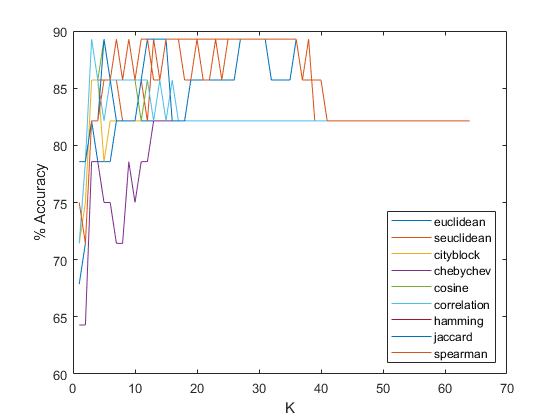

[trm,~] = size(train_class);
train_vclass = zeros(trm,1);
for j=1:trm
    if train_class(j,1)==0 && train_class(i,2)==1
        train_vclass(j,1) = 1;
    else
        train_vclass(j,1) = 2;
    end
end

dist = ["euclidean", "seuclidean", "cityblock", ...
    "chebychev", "cosine", "correlation", "hamming", "jaccard", "spearman"];

[M,F] = mode([train_vclass;val_vclass;test_vclass]);
K = 2*(length([train_vclass;val_vclass;test_vclass])-F);

val_accu_mat = zeros(K,9);
for i = 1:K
    for l = 1:9
        [eucValIdx, eucValVar] = knnsearch(train_var,val_var,"Distance",dist(l),"K",i);
        
        val_pclass = zeros(valm,1);
        
        class_vec = zeros(i,1);
        for j=1:valm
            for k = 1:i
                class_vec(k,1) = train_vclass(eucValIdx(j,k));
            end
            val_pclass(j) = mode(class_vec);
        end
        val_conf = confusionmat(val_vclass,val_pclass);
        val_accu = (val_conf(2,2)+val_conf(1,1))/(sum(val_conf,'all'))*100;
        
        val_accu_mat(i,l) = val_accu;
    end
end

figure(1)
for i=1:l
   plot(1:K,val_accu_mat(:,i));
   hold on
end
hold off
ylabel("% Accuracy");
xlabel("K")
legend(["euclidean", "seuclidean", "cityblock", ...
    "chebychev", "cosine", "correlation", "hamming", "jaccard", "spearman"],...

    "Location","SouthEast")
[accM,accIdx] = max(val_accu_mat,[],"all","linear");
[maxK,maxAcc] = ind2sub(size(val_accu_mat),accIdx);
val_accu_table = array2table(val_accu_mat);
val_accu_table.Properties.VariableNames = ["euclidean", "seuclidean", "cityblock", ...
    "chebychev", "cosine", "correlation", "hamming", "jaccard", "spearman"];
for i=1:K
    Karr(i) = "K"+int2str(i);
end
val_accu_table.Properties.RowNames = Karr;

val_accu_table = 64×9 table
           euclidean    seuclidean    cityblock    chebychev    cosine    correlation    hamming    jaccard    spearman
           _________    __________    _________    _________    ______    ___________    _______    _______    ________

    K1      67.857        78.571       71.429       64.286      71.429      71.429       78.571     78.571          75 
    K2      71.429        78.571           75       64.286      78.571      78.571       78.571     78.571      71.429 
    K3      82.143        89.286       85.714       78.571      89.286      89.286       82.143     82.143      82.143 
    K4

Valor maximo de accuracy y su respectivo K

val_accu_table(val_accu_table.Properties.RowNames(maxK),...

ans = table
          seuclidean
          __________

    K3      89.286  


    val_accu_table.Properties.VariableNames(maxAcc))